
dsf1_1=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_1_1_VMDFilt.csv'); % reading the preprocessed data of bearing 1-1
dsf1_2=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_1_2_VMDFilt.csv');
dsf2_1=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_2_1_VMDFilt.csv'); % reading the preprocessed data of bearing 1-1
dsf2_2=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_2_2_VMDFilt.csv');
dsf3_1=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_3_1_VMDFilt.csv'); % reading the preprocessed data of bearing 1-1
dsf3_2=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Learning Set\Bearing_3_2_VMDFilt.csv');
dsf1_3=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_1_3_VMDFilt.csv'); 
dsf1_4=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_1_4_VMDFilt.csv'); 
dsf1_5=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_1_5_VMDFilt.csv');
dsf1_6=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_1_6_VMDFilt.csv'); 
dsf1_7=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_1_7_VMDFilt.csv'); 
dsf2_3=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_2_3_VMDFilt.csv'); 
dsf2_4=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_2_4_VMDFilt.csv'); 
dsf2_5=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_2_5_VMDFilt.csv');
dsf2_6=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_2_6_VMDFilt.csv'); 
dsf2_7=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_2_7_VMDFilt.csv'); 
dsf3_3=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\Filtered Dataset\VMD_Filtered\Test Set\Bearing_3_3_VMDFilt.csv');


data=readall(dsf2_1);
f='Bearing 2_5'

f = 'Bearing 2_5'

sig=data.Var1;
t=linspace(1/128,length(sig)/128,length(sig));

figure1=figure("Color",[1 1 1],"Name",f);
tiledlayout(2,1);

nexttile
plot(t,sig)
set(gca,'FontName','Times New Roman','FontSize',24,'FontWeight','bold','LineWidth',2);
xlabel('Time(s)','FontName','Times New Roman','FontSize',24,'FontWeight','bold')
ylabel('Acceleration(g)','FontName','Times New Roman','FontSize',24,'FontWeight','bold')
title(f)
nexttile
p=pentropy(sig,128);
t1=linspace(1/128,length(sig)/128,length(p))';
[xData, yData] = prepareCurveData( t1, p );

% Set up fittype and options.
ft = fittype('poly9');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

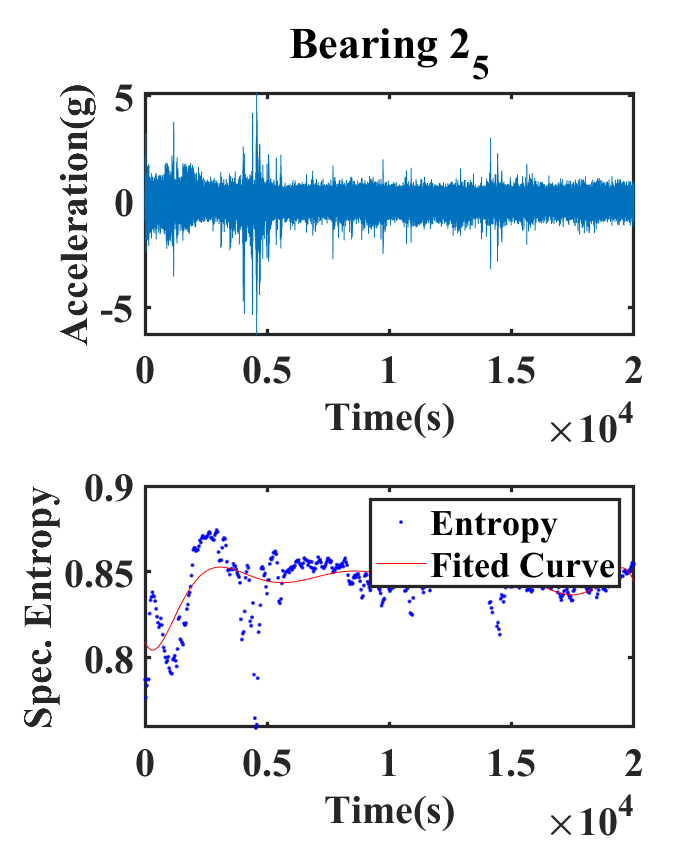

plot( fitresult, xData, yData);
legend('Entropy','Fited Curve')
set(gca,'FontName','Times New Roman','FontSize',24,'FontWeight','bold','LineWidth',2);
xlabel('Time(s)','FontName','Times New Roman','FontSize',24,'FontWeight','bold')
ylabel('Spec. Entropy','FontName','Times New Roman','FontSize',24,'FontWeight','bold')
set(figure1,"Visible","on")
savefig(figure1,['C:\Users\V      aibhav Baldua\OneDrive\Desktop\DSP exp 2\Fault Classification\Test Set\' f '.fig'])